# Notch Filter

The following example will demonstrate behaviour of notch filter.

A notch filter is a specific band-stop filter, which attenuates signals around its resonant frequency and passes the signals of other frequencies unaltered. 

A typical notch filter has a frequency response defined as


$$H(\omega)=\frac{(1-e^{-j(\omega-\omega_0)})(1-e^{-j(\omega+\omega_0)})}{(1-re^{-j(\omega-\omega_0)})(1-re^{-j(\omega+\omega_0)})}$$


In Matlab, visualise its magnitude response$H(\omega)$in the range $0 \le \omega \le \pi$ for $f=500Hz$. Use a sampling rate of $f_s=8kHz$ and $r = 0.95$. Use a logarithmic scale.

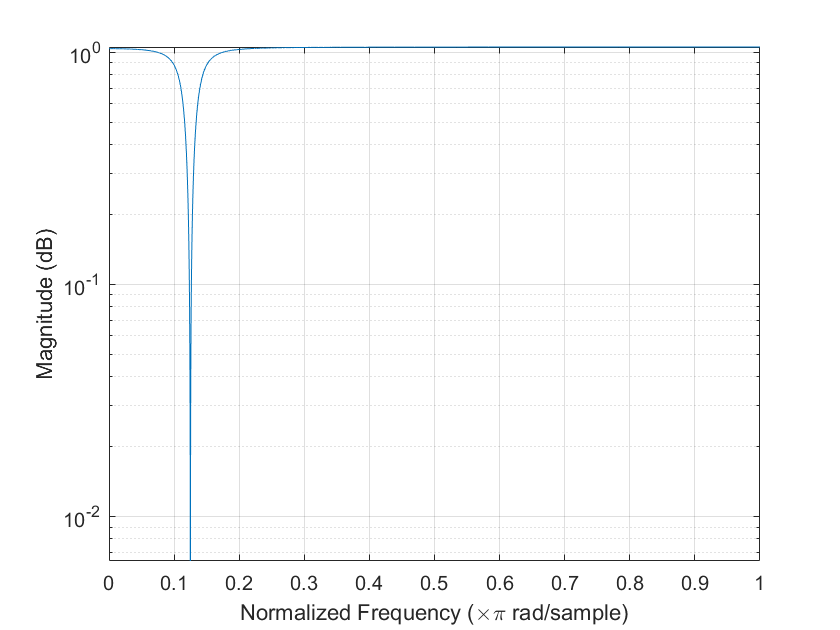

r=0.95;
f=500;
fs=8E3;
resolution=1/10000;
w0=2*pi*f/fs;
w=(0:resolution:1)*pi;
H=(1-exp(-1i*(w-w0))).*(1-exp(-1i*(w+w0)))./((1-r*exp(-1i*(w-w0))).*(1-r*exp(-1i*(w+w0))));
semilogy(w/pi,abs(H));
ax = gca;
ax.XTick = 0:.1:1;
grid on;
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

Determine numerator and denominator coefficients ***b*** and ***a*** of a corresponding 2nd order IIR filter $H(z) =\frac{b_0+b_1z^{-1}+b_2 z^{-2}}{a_o + a_1 z^{-1}+a_2 z ^{-2}}$. Use the known relation $z=e^{j \omega}$ on the unit circle. Verify the results by plotting the frequency response of a corresponding filter

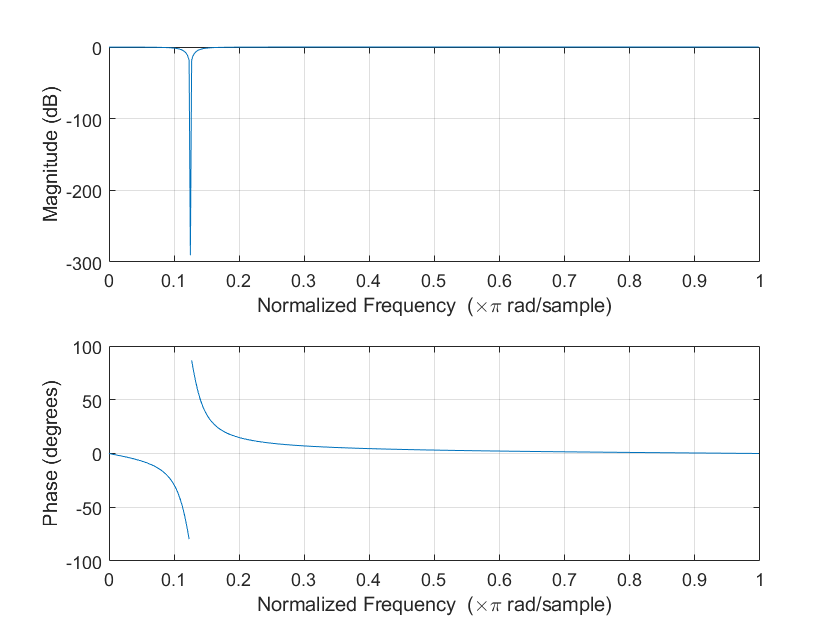

b=[1 -2*cos(w0) 1];
a=[1 -2*r*cos(w0) r^2];
freqz(b,a)

Show the pole-zero plot of the designed filter!

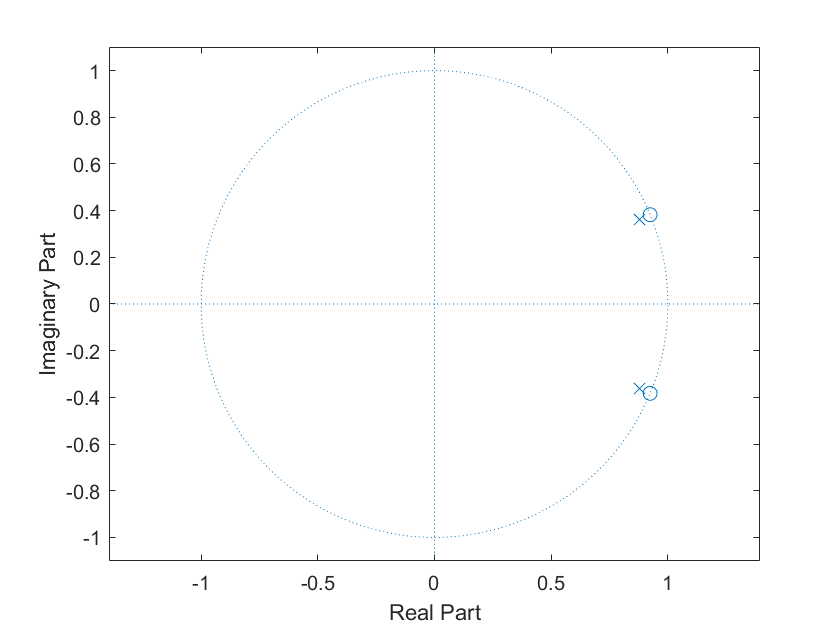

zplane(roots(b), roots(a));

Define a sine signal of 500 Hz in the duration of 10ms and plot the time response of the notch filter. 

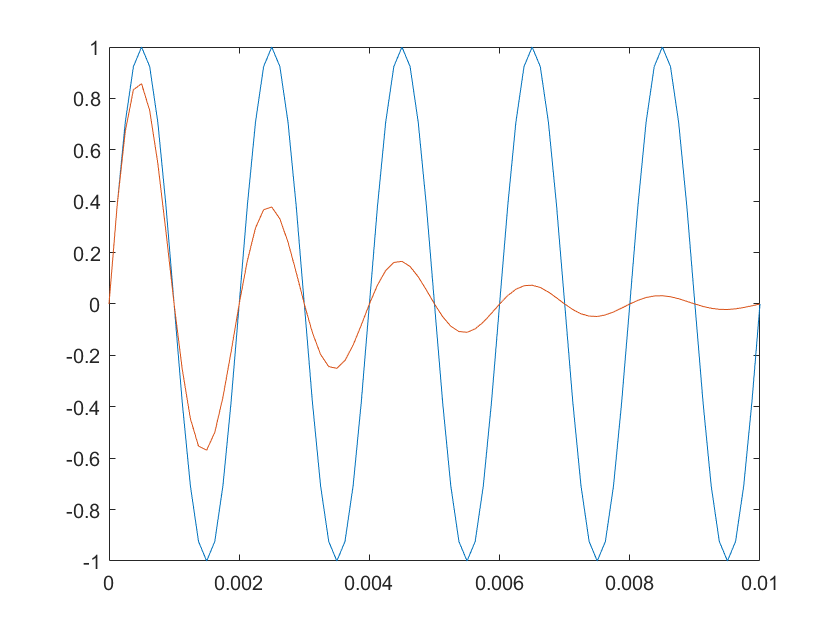

Tmax=0.01;
t=0:1/fs:0.01;
x=sin(2*pi*f*t);
y=filter(b,a,x);
% ts = timescope(SampleRate=fs, ...
%                ChannelNames={'Input', 'Output'},...
%                YLimits=[-3,3]);
% ts(x, y);
plot(t,x,t,y)
axis([0 Tmax -1 1])

Now play the 'noisy' 500Hz music.

x=audioread("handel_500.wav");
y=filter(b,a,x);
return;

p1=audioplayer(x,fs);
play(p1)
 

p2=audioplayer(y,fs);
play(p2)
 